# Generate functions for each equation of motion

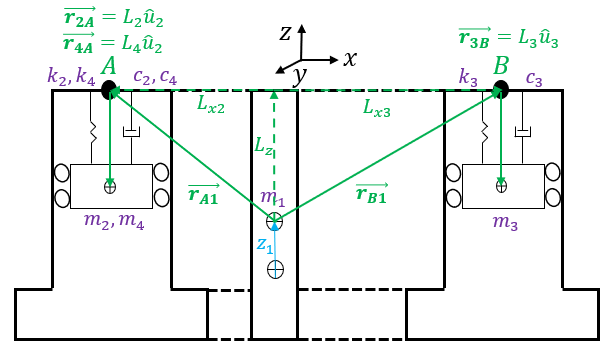

clear; clc; warning off;

## Create symbolic variables

syms z1_t(t) L2_t(t) L3_t(t) L4_t(t) w j_w real % displacements as a function of time
syms z1 L2 L3 L4 real % variables to sub in after taking derivatives
syms z1_dot L2_dot L3_dot L4_dot real % variables to sub in after taking derivatives
syms z1_ddot L2_ddot L3_ddot L4_ddot real % variables to sub in after taking derivatives
syms z1_w L2_w L3_w L4_w w real % variables to sub in after fourier transform

syms L_z real % body fixed vector components
syms L2_0 L3_0 L4_0 real % initial positions of the masses and initial rotation angle
syms m2 m3 m4 k2 k3 k4 c2 c3 c4 real % TMD parameters
syms m1 real % platform parameters
syms A33 C33 F33 K33 real  % BEM parameters

## Define initial body fixed vectors and initial rotation matrix

u = -1;

## Define body fixed vectors and rotation matrix

z_A1 = L_z;
z_B1 = L_z;
z_C1 = L_z;

z_2A = L2_t(t)*u;
z_3B = L3_t(t)*u;
z_4C = L4_t(t)*u;

z_2A_dot = diff(z_2A,t);
z_3B_dot = diff(z_3B,t);
z_4C_dot = diff(z_4C,t);

## Define global vectors

z_1 = z1_t(t);

z_A = z_A1 + z_1;
z_B = z_B1 + z_1;
z_C = z_C1 + z_1;

z_2 = z_A + z_2A;
z_3 = z_B + z_3B;
z_4 = z_C + z_4C;

z_A_dot = diff(z_A,t);
z_B_dot = diff(z_B,t);
z_C_dot = diff(z_C,t);

z_2_dot = diff(z_2,t);
z_3_dot = diff(z_3,t);
z_4_dot = diff(z_4,t);

## Define Energies

T = (1/2)*(m1+A33)*diff(z1_t(t),t)^2 + (1/2)*m2*z_2_dot^2 + ...
    + (1/2)*m3*z_3_dot^2 + (1/2)*m4*z_4_dot^2;

U = (1/2)*K33*z1_t(t)^2 + (1/2)*k2*(L2_0 - L2_t(t))^2 + ...
    + (1/2)*k3*(L3_0 - L3_t(t))^2  + (1/2)*k4*(L4_0 - L4_t(t))^2;

R = (1/2)*C33*diff(z1_t(t),t)^2 + (1/2)*c2*(diff(L2_t(t),t))^2 + ...
    + (1/2)*c3*(diff(L3_t(t),t))^2 + (1/2)*c4*(diff(L4_t(t),t))^2;

L = T - U;

## Calculate the equations of motion using the lagrange equation


$$\frac{d}{\textrm{dt}}\frac{\partial L}{{\partial \dot{q} }_i }-\frac{\partial L}{{\partial q}_i }+\frac{\partial R}{{\partial \dot{q} }_i }=0$$


EOM_z1_t = diff(diff(L,diff(z1_t,t)),t) - diff(L,z1_t) + diff(R,diff(z1_t,t)) == 0;
EOM_L2_t = diff(diff(L,diff(L2_t,t)),t) - diff(L,L2_t) + diff(R,diff(L2_t,t)) == 0;
EOM_L3_t = diff(diff(L,diff(L3_t,t)),t) - diff(L,L3_t) + diff(R,diff(L3_t,t)) == 0;
EOM_L4_t = diff(diff(L,diff(L4_t,t)),t) - diff(L,L4_t) + diff(R,diff(L4_t,t)) == 0;

## Substitute in the non time dependent parameters

EOM_z1 = subs(EOM_z1_t,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_z1 = subs(EOM_z1,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_z1 = subs(EOM_z1,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_z1 = subs(EOM_z1,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

EOM_L2 = subs(EOM_L2_t,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_L2 = subs(EOM_L2,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_L2 = subs(EOM_L2,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_L2 = subs(EOM_L2,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

EOM_L3 = subs(EOM_L3_t,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_L3 = subs(EOM_L3,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_L3 = subs(EOM_L3,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_L3 = subs(EOM_L3,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

EOM_L4 = subs(EOM_L4_t,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_L4 = subs(EOM_L4,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_L4 = subs(EOM_L4,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_L4 = subs(EOM_L4,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

## Split equations into matrices

[A,b] = equationsToMatrix([EOM_z1,EOM_L2,EOM_L3,EOM_L4],[z1_ddot,L2_ddot,L3_ddot,L4_ddot]);
left_hand_matrix = A;
right_hand_vector = b;

## Define matlab function for each matrix

matlabFunction(left_hand_matrix,'File','ode/calculate_left_hand_matrix_heave_TMD');
matlabFunction(right_hand_vector,'File','ode/calculate_right_hand_vector_heave_TMD');

## Sub values into energies

T = subs(T,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
T = subs(T,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
T = subs(T,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
T = subs(T,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

U = subs(U,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
U = subs(U,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
U = subs(U,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
U = subs(U,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

## Define matlab function for energies

matlabFunction(T,'File','energy/calculate_kinetic_energy_heave_TMD');
matlabFunction(U,'File','energy/calculate_potential_energy_heave_TMD');

## Manual fourier transform

EOM_z1_w = subs(EOM_z1,[z1,z1_dot,z1_ddot],[z1_w,j_w*w*z1_w,-w^2*z1_w]);
EOM_z1_w = subs(EOM_z1_w,[L2,L2_dot,L2_ddot],[L2_w,j_w*w*L2_w,-w^2*L2_w]);
EOM_z1_w = subs(EOM_z1_w,[L3,L3_dot,L3_ddot],[L3_w,j_w*w*L3_w,-w^2*L3_w]);
EOM_z1_w = subs(EOM_z1_w,[L4,L4_dot,L4_ddot],[L4_w,j_w*w*L4_w,-w^2*L4_w]);

EOM_L2_w = subs(EOM_L2,[z1,z1_dot,z1_ddot],[z1_w,j_w*w*z1_w,-w^2*z1_w]);
EOM_L2_w = subs(EOM_L2_w,[L2,L2_dot,L2_ddot],[L2_w,j_w*w*L2_w,-w^2*L2_w]);
EOM_L2_w = subs(EOM_L2_w,[L3,L3_dot,L3_ddot],[L3_w,j_w*w*L3_w,-w^2*L3_w]);
EOM_L2_w = subs(EOM_L2_w,[L4,L4_dot,L4_ddot],[L4_w,j_w*w*L4_w,-w^2*L4_w]);

EOM_L3_w = subs(EOM_L3,[z1,z1_dot,z1_ddot],[z1_w,j_w*w*z1_w,-w^2*z1_w]);
EOM_L3_w = subs(EOM_L3_w,[L2,L2_dot,L2_ddot],[L2_w,j_w*w*L2_w,-w^2*L2_w]);
EOM_L3_w = subs(EOM_L3_w,[L3,L3_dot,L3_ddot],[L3_w,j_w*w*L3_w,-w^2*L3_w]);
EOM_L3_w = subs(EOM_L3_w,[L4,L4_dot,L4_ddot],[L4_w,j_w*w*L4_w,-w^2*L4_w]);

EOM_L4_w = subs(EOM_L4,[z1,z1_dot,z1_ddot],[z1_w,j_w*w*z1_w,-w^2*z1_w]);
EOM_L4_w = subs(EOM_L4_w,[L2,L2_dot,L2_ddot],[L2_w,j_w*w*L2_w,-w^2*L2_w]);
EOM_L4_w = subs(EOM_L4_w,[L3,L3_dot,L3_ddot],[L3_w,j_w*w*L3_w,-w^2*L3_w]);
EOM_L4_w = subs(EOM_L4_w,[L4,L4_dot,L4_ddot],[L4_w,j_w*w*L4_w,-w^2*L4_w]);

## Split equations into matrices

[A,b] = equationsToMatrix([EOM_z1_w,EOM_L2_w,EOM_L3_w,EOM_L4_w],[z1_w,L2_w,L3_w,L4_w]);
left_hand_matrix = A;
right_hand_vector = b;

## Define matlab function for each matrix

matlabFunction(left_hand_matrix,'File','frequency/calculate_left_hand_matrix_FD_TMD');
matlabFunction(right_hand_vector,'File','frequency/calculate_right_hand_vector_FD_TMD');